# Linear Regressions

## Exercises

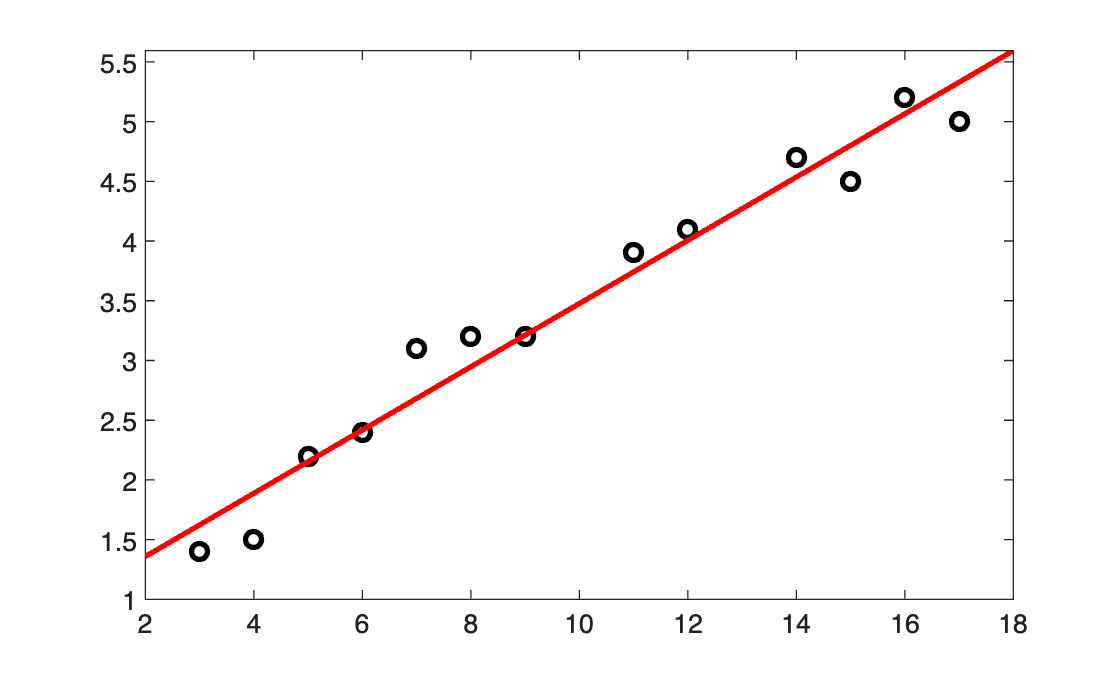

% Load and plot data
dataX = [3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   11.0000   12.0000   14.0000   15.0000   16.0000   17.0000]';
dataY = [1.4000    1.5000    2.2000    2.4000    3.1000    3.2000    3.2000    3.9000    4.1000    4.7000    4.5000    5.2000    5.0000]';
n = length(dataX);
figure;
plot(dataX, dataY, 'ko', 'LineWidth',2)

% Calculate and plot the regression line using the equations from the
% tutorial
num = sum(dataX .* dataY) - (sum(dataX)*sum(dataY))/n;
denom = sum(dataX.^2) - ((sum(dataX))^2/n);
b = num/denom; 
a = mean(dataY) - b * mean(dataX); 

% Plot as a reference line
hold on; 
hline = refline(b, a); 
hline.LineWidth = 2;
hline.Color = 'r';


% Use built-in matlab functions to calculate pertinent stats
% P value of the intercept is small enough to reject the null
tbl = table(dataX, dataY);
mdl = fitlm(tbl, 'dataY ~ dataX');
disp(mdl)


Linear regression model:
    dataY ~ 1 + dataX

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.82962      0.16774    4.9459    0.00043849
    dataX          0.26468     0.015559    17.012    3.0097e-09


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.256
R-squared: 0.963,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 289, p-value = 3.01e-09


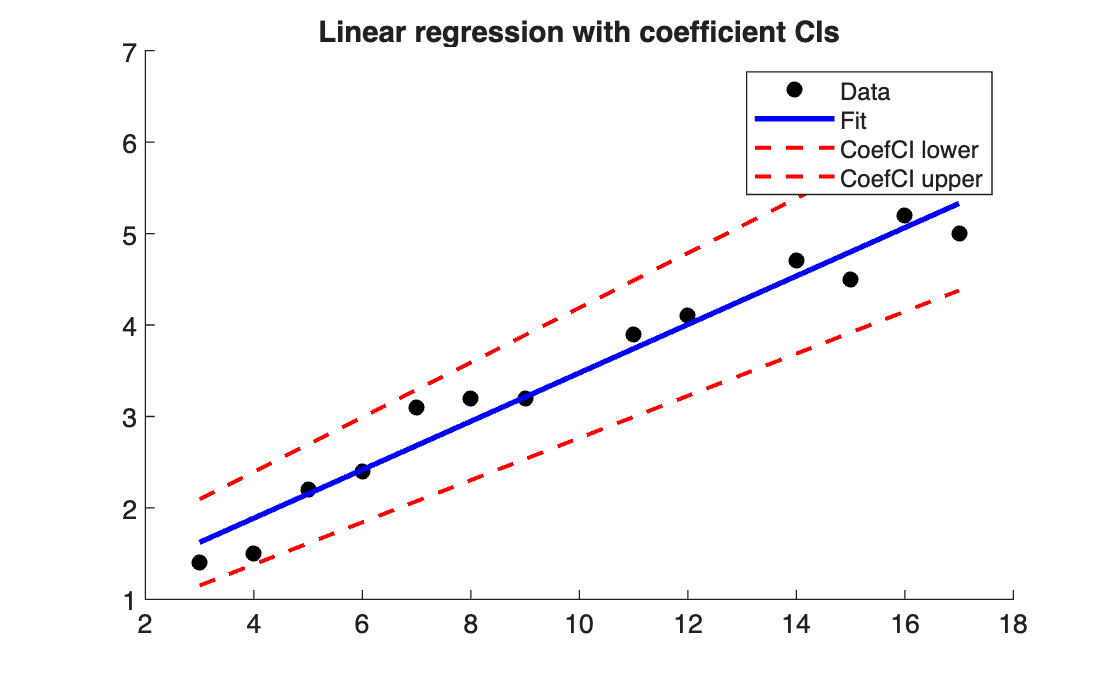

ci = coefCI(mdl);
bNew = mdl.Coefficients.Estimate;

% Lines for lower and upper slope/intercept
xnew = linspace(min(dataX),max(dataX),100)';
y_low  = ci(1,1) + ci(2,1)*xnew;   % lower bound line
y_high = ci(1,2) + ci(2,2)*xnew;   % upper bound line
y_hat  = bNew(1) + bNew(2)*xnew;         % fitted line

% Plot the results using code generated by ChatGPT
figure; hold on
scatter(dataX,dataY,'ko','filled')
plot(xnew,y_hat,'b-','LineWidth',2)
plot(xnew,y_low,'r--','LineWidth',1.5)
plot(xnew,y_high,'r--','LineWidth',1.5)
legend('Data','Fit','CoefCI lower','CoefCI upper')
title('Linear regression with coefficient CIs')


% Calculate the Pearson's r
r_Pearson = corrcoef([dataX dataY]);
fprintf('Pearsons r = %0.4f', r_Pearson(2))

Pearsons r = 0.9815

## With Noise


% Add noise to y values and replot along with regression line
% Just multiply data points by some scalar and adjusting spread for ease of
% visibility. Then replot everything above. As before
dataY_Noisy = abs(randn(size(dataY)) * 0.5) .* dataY; 

% Use built-in matlab functions to calculate pertinent stats
% P value of the intercept is small enough to reject the null
tbl = table(dataX, dataY_Noisy);
mdl = fitlm(tbl, 'dataY_Noisy ~ dataX');
disp(mdl)


Linear regression model:
    dataY_Noisy ~ 1 + dataX

Estimated Coefficients:
                   Estimate       SE        tStat       pValue 
                   ________    ________    ________    ________

    (Intercept)    0.047423     0.57049    0.083127     0.93524
    dataX           0.15878    0.052916      3.0007    0.012066


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.87
R-squared: 0.45,  Adjusted R-Squared: 0.4
F-statistic vs. constant model: 9, p-value = 0.0121


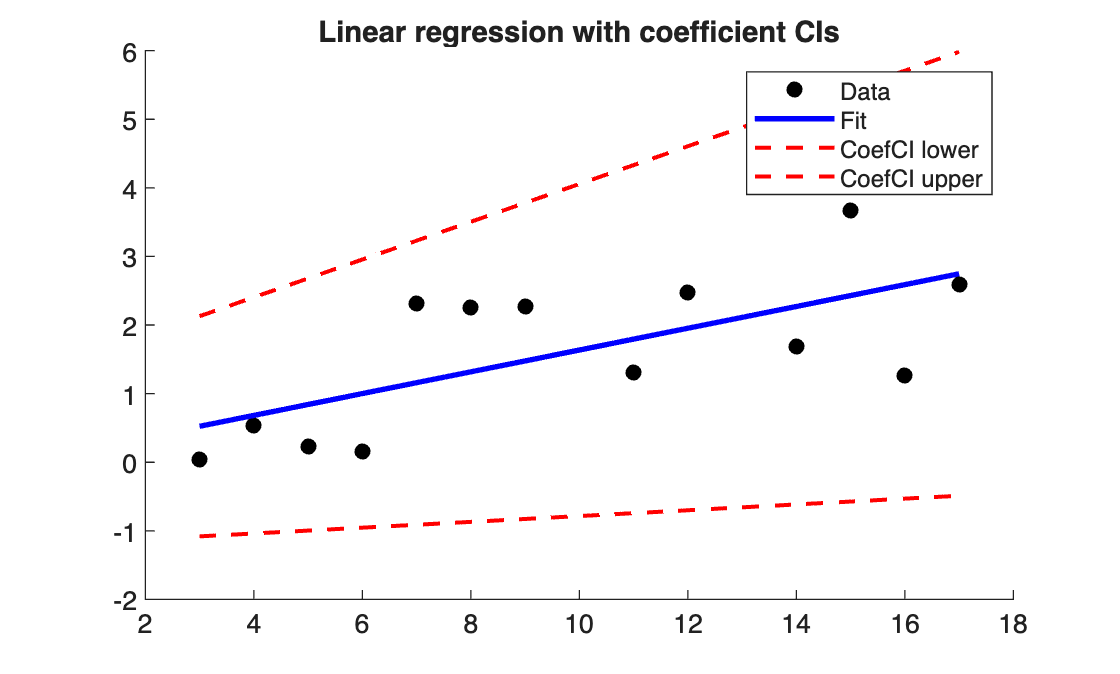

ci = coefCI(mdl);
bNew = mdl.Coefficients.Estimate;

% Lines for lower and upper slope/intercept
xnew = linspace(min(dataX),max(dataX),100)';
y_low  = ci(1,1) + ci(2,1)*xnew;   % lower bound line
y_high = ci(1,2) + ci(2,2)*xnew;   % upper bound line
y_hat  = bNew(1) + bNew(2)*xnew;         % fitted line

% Plot the results using code generated by ChatGPT
figure; hold on
scatter(dataX,dataY_Noisy,'ko','filled')
plot(xnew,y_hat,'b-','LineWidth',2)
plot(xnew,y_low,'r--','LineWidth',1.5)
plot(xnew,y_high,'r--','LineWidth',1.5)
legend('Data','Fit','CoefCI lower','CoefCI upper')
title('Linear regression with coefficient CIs')


% Calculate the Pearson's r
r_PearsonNoisy = corrcoef([dataX dataY_Noisy]);
fprintf('Pearsons r = %0.4f', r_PearsonNoisy(2))

Pearsons r = 0.6709